This scrip is used to read h5 file and plotting.

timestep=100;
simu_number=300;
totel_length=100;
head_index=1;
tail_index=100;
force_field=['V1(x,y,z)=1000(r-2);V2=0.5r^2 n=',num2str(head_index),',',num2str(tail_index)];
%force_field=['V(x,y,z)=(x^2+y^2+z^2) n=',num2str(head_index),',',num2str(tail_index)];
time_step_str='100vLt';

get pos-data

MSD_xyz=[];
for xyz=1:3
    head_pos_list=[];%3dm*n*l, m is xyz, n is timestep, l is polymer number
    tail_pos_list=[];
    average_time_list=[0]*1000;
    for i=0:simu_number-1
        head_pos=[];
        tail_pos=[];
        time_step=[];
        for j=0
            F=['trajectory',num2str(i),'/blocks_',num2str(j*100),'-',num2str(j*100+99),'.h5'];
            for k=(100*j):(100*j+99)
                pos = h5read(F,['////',num2str(k),'/pos']);
                head_pos=[head_pos,pos(xyz,head_index)];
                tail_pos=[tail_pos,pos(xyz,tail_index)];
                time=h5readatt(F,['////',num2str(k)],'time');
                time_step=[time_step,time];
            end
        end
        head_pos_list=[head_pos_list;head_pos];
        tail_pos_list=[tail_pos_list;tail_pos];
        average_time_list=average_time_list+time_step/simu_number;
    end
    MSD_t=[];
    for t=1:timestep
        MSD=0;
        for n=1:simu_number
            MSD=MSD+(tail_pos_list(n,t)-head_pos_list(n,t))^2/simu_number;
        end
        MSD_t=[MSD_t,MSD];
    end
    MSD_xyz=[MSD_xyz;MSD_t];
end
MSD_average=(MSD_xyz(1,:)+MSD_xyz(2,:)+MSD_xyz(3,:))/3;

Plotting

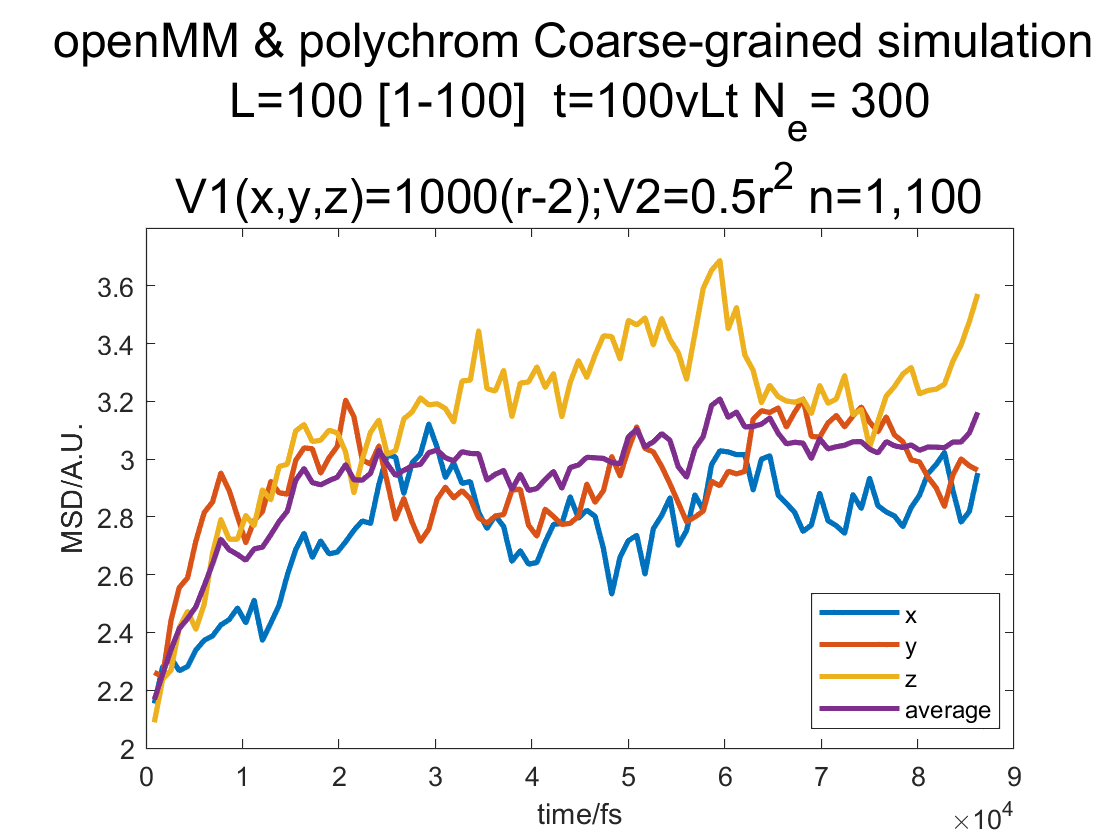

figure
plot(average_time_list(1,:),MSD_xyz(1,:),"LineWidth",2,'DisplayName','x')
hold on
plot(average_time_list(1,:),MSD_xyz(2,:),"LineWidth",2,'DisplayName','y')
plot(average_time_list(1,:),MSD_xyz(3,:),"LineWidth",2,'DisplayName','z')
plot(average_time_list(1,:),MSD_average,"LineWidth",2,'DisplayName','average')
legend("Location","best");
title({'openMM & polychrom Coarse-grained simulation ';['L=',num2str(totel_length),' [',num2str(head_index),'-',num2str(tail_index),'] ',' t=',time_step_str,' N_e= ',num2str(simu_number)];force_field},"fontsize",18)
xlabel('time/fs')
ylabel('MSD/A.U.')

Saving

saving_location='C:\Users\zhouquan\OneDrive\research\polychrom simulation\MSDData';
save([saving_location,'\MSD of ',force_field,',N=',num2str(totel_length),',Ne=',num2str(simu_number),',timestep=',time_step_str,datestr(now,' yyyy-mm-dd HH'),'.mat'],'totel_length','head_index','tail_index','average_time_list',"MSD_average",'MSD_xyz','force_field','time_step_str')

